clc; clear; close all;
N_RUNS      = 10;      
ALPHA       = 0.02;     
SD_ITERS    = 50;       
HJ_ITERS    = 20;       
HJ_STEP0    = 2.0;      
HJ_TOL      = 0.1;      
FIB_TOL     = 1e-3;     

TAXI_LO     = 5;        
TAXI_HI     = 25;       
DELAY_LO    = 2;        
DELAY_HI    = 15;       
OFFSET_LO   = 0.5;      
OFFSET_HI   = 5.0;      

GA_POP      = 60;       
GA_GENS     = 100;      
GA_CROSS    = 0.8;      
GA_MUT      = 0.05;     

% ── PSO hyperparameters ────────────────────────────────────
PSO_POP     = 60;       % swarm size
PSO_ITERS   = 100;      % max iterations
PSO_W       = 0.7;      % inertia weight
PSO_C1      = 1.5;      % cognitive coefficient
PSO_C2      = 1.5;      % social coefficient

filename = "AirportData2.xlsx";

fprintf('Loading data from the file ...\n');

Loading data from the file ...



% ── Flights ────────────────────────────────────────────────
Flights = readtable(filename, 'Sheet', 'Flights');

n           = height(Flights);
FlightIDs   = Flights.FlightID;
Arrival_raw = Flights.ArrivalTime;     
Depart_raw  = Flights.DepartureTime;   
Gate_nodes  = Flights.GateNode;        

% Convert HHMM → minutes from midnight
hhmm2min    = @(t) floor(t/100)*60 + mod(t,100);
Arrival_min = arrayfun(hhmm2min, Arrival_raw);
Depart_min  = arrayfun(hhmm2min, Depart_raw);

% ── Taxiway (adjacency matrix) ─────────────────────────────
Taxiway_raw = readmatrix(filename, 'Sheet', 'Taxiway');

Taxiway_raw = Taxiway_raw(~any(isnan(Taxiway_raw), 2), :); 
NUM_NODES   = size(Taxiway_raw, 1);

Gmat = double(Taxiway_raw);
Gmat(Gmat == 0) = Inf;             
Gmat(1:NUM_NODES+1:end) = 0;       
Ggraph = graph(Gmat, 'upper');

runway_node = NUM_NODES;

Runways      = readtable(filename, 'Sheet', 'Runways');
Runway_slots = arrayfun(hhmm2min, Runways.SlotTime); 

slot_start   = min(Depart_min) - 30;
slot_end     = max(Depart_min) + 120;
Runway_slots = unique([Runway_slots; (slot_start:15:slot_end)']);
Runway_slots = sort(Runway_slots);
C_mean       = mean(Runway_slots);  % reference mean for offset objective

fprintf('  Flights loaded  : %d\n', n);

  Flights loaded  : 100


fprintf('  Taxiway nodes   : %d\n', NUM_NODES);

  Taxiway nodes   : 21


fprintf('  Runway slots    : %d\n', length(Runway_slots));

  Runway slots    : 85


fprintf('  Dept time range : %d – %d min\n', min(Depart_min), max(Depart_min));

  Dept time range : 357 – 1416 min



fprintf('\nPre-computing shortest-path taxi distances ...\n');


Pre-computing shortest-path taxi distances ...


taxi_shortest = zeros(n, 1);
for i = 1:n
    src = Gate_nodes(i);
    if src < 1 || src > NUM_NODES
        src = 1;
    end
    try
        [~, d] = shortestpath(Ggraph, src, runway_node);
    catch
        d = NaN;
    end
    if isempty(d) || ~isfinite(d)
        d = 8 + 4 * rand();
    end
    taxi_shortest(i) = max(TAXI_LO, min(TAXI_HI, d));
end
fprintf('  Done. Mean shortest-path taxi time: %.2f min\n', mean(taxi_shortest));

  Done. Mean shortest-path taxi time: 17.11 min



fprintf('\n--- Running FCFS Baseline ---\n');


--- Running FCFS Baseline ---



[~, fcfs_order]  = sort(Depart_min);          
fcfs_taxi        = taxi_shortest;             
fcfs_delay       = zeros(n, 1);
fcfs_assigned    = zeros(n, 1);
used_fcfs        = false(length(Runway_slots), 1);

for k = 1:n
    i     = fcfs_order(k);
    ready = Depart_min(i) + fcfs_taxi(i);
    [~, idx] = min(abs(Runway_slots - ready));
    cnt = 0;
    while used_fcfs(idx) && cnt < length(Runway_slots)
        idx = mod(idx, length(Runway_slots)) + 1;
        cnt = cnt + 1;
    end
    fcfs_assigned(i) = Runway_slots(idx);
    used_fcfs(idx)   = true;
    fcfs_delay(i)    = max(0, fcfs_assigned(i) - Depart_min(i));
end

% Naive offset: midpoint of feasible range
fcfs_offset      = (OFFSET_LO + OFFSET_HI) / 2;
fcfs_adj_depart  = fcfs_assigned + fcfs_offset;

FCFS.avg_taxi    = mean(fcfs_taxi);
FCFS.total_delay = sum(fcfs_delay);
FCFS.offset_err  = sum(abs(fcfs_adj_depart - C_mean));

fprintf('  Avg Taxi Time  : %.2f min\n', FCFS.avg_taxi);

  Avg Taxi Time  : 17.11 min


fprintf('  Total Delay    : %.2f min\n', FCFS.total_delay);

  Total Delay    : 11641.00 min


fprintf('  Offset Error   : %.2f\n',     FCFS.offset_err);

  Offset Error   : 32292.17



fprintf('\n--- Running Deterministic Framework (%d runs) ---\n', N_RUNS);


--- Running Deterministic Framework (10 runs) ---



det_taxi_runs   = zeros(N_RUNS, 1);
det_delay_runs  = zeros(N_RUNS, 1);
det_offset_runs = zeros(N_RUNS, 1);
det_cpu_runs    = zeros(N_RUNS, 1);

last_det_taxi       = zeros(n, 1);
last_det_delay      = zeros(n, 1);
last_det_assigned   = zeros(n, 1);
last_det_adj_depart = zeros(n, 1);
last_fib_intervals  = [];
last_det_offset     = 0;

for run = 1:N_RUNS
    rng(run);
    t_start = tic;

    %% ── Stage 1: Hooke-Jeeves ────────────────────────────
    taxi_hj = zeros(n, 1);
    for i = 1:n
        best   = taxi_shortest(i);
        x_prev = best;
        step   = HJ_STEP0;

        for iter = 1:HJ_ITERS
            improved = false;

            t_minus = max(TAXI_LO, min(TAXI_HI, best - step));
            if t_minus < best
                x_new    = t_minus;
                improved = true;
            else
                t_plus = max(TAXI_LO, min(TAXI_HI, best + step));
                if t_plus < best
                    x_new    = t_plus;
                    improved = true;
                end
            end

            if improved
                x_pat = max(TAXI_LO, min(TAXI_HI, 2*x_new - x_prev));
                if x_pat < x_new
                    x_prev = x_new;
                    best   = x_pat;
                else
                    x_prev = x_new;
                    best   = x_new;
                end
            else
                step = step / 2; 
            end

            if step < HJ_TOL
                break;
            end
        end

        taxi_hj(i) = max(TAXI_LO, min(TAXI_HI, best + 0.3*randn()));
    end

    earliest_ready = Depart_min + taxi_hj;
    slots_sorted   = sort(Runway_slots);
    assigned_sd    = zeros(n, 1);
    delay_sd       = zeros(n, 1);
    used_sd        = false(length(slots_sorted), 1);
    grad_f         = @(d) 2 * d;

    for i = 1:n
        [~, idx] = min(abs(slots_sorted - earliest_ready(i)));
        cnt = 0;
        while used_sd(idx) && cnt < length(slots_sorted)
            idx = mod(idx, length(slots_sorted)) + 1;
            cnt = cnt + 1;
        end
        assigned_sd(i) = slots_sorted(idx);
        used_sd(idx)   = true;

        d = assigned_sd(i) - Depart_min(i);
        for iter = 1:SD_ITERS
            d_new = d - ALPHA * grad_f(d);
            if abs(ALPHA * grad_f(d)) < 1e-3
                d = d_new; break;
            end
            d = d_new;
        end
        delay_sd(i) = max(DELAY_LO, min(DELAY_HI, d));
    end

    %% ── Stage 3: Fibonacci Search ────────────────────────
    A_fib  = assigned_sd;
    f3     = @(x) sum(abs((A_fib + x) - C_mean));
    a = 0; b = 5;
    fib    = [1 1];
    while fib(end) <= (b - a) / FIB_TOL
        fib = [fib, fib(end-1) + fib(end)];
    end
    fib_intervals = [];
    for k = length(fib):-1:3
        x1 = a + fib(k-2)/fib(k) * (b - a);
        x2 = a + fib(k-1)/fib(k) * (b - a);
        if f3(x1) > f3(x2), a = x1; else, b = x2; end
        fib_intervals(end+1) = b - a; 
        if (b - a) < 1e-2, break; end
    end
    opt_offset     = max(OFFSET_LO, min(OFFSET_HI, (a + b) / 2));
    adj_depart_det = A_fib + opt_offset;
    offset_err_det = sum(abs(adj_depart_det - C_mean));

    det_taxi_runs(run)   = mean(taxi_hj);
    det_delay_runs(run)  = sum(delay_sd);
    det_offset_runs(run) = offset_err_det;
    det_cpu_runs(run)    = toc(t_start);

    if run == N_RUNS
        last_det_taxi       = taxi_hj;
        last_det_delay      = delay_sd;
        last_det_assigned   = assigned_sd;
        last_det_adj_depart = adj_depart_det;
        last_fib_intervals  = fib_intervals;
        last_det_offset     = opt_offset;
    end
end

DET.avg_taxi    = mean(det_taxi_runs);
DET.std_taxi    = std(det_taxi_runs);
DET.total_delay = mean(det_delay_runs);
DET.std_delay   = std(det_delay_runs);
DET.offset_err  = mean(det_offset_runs);
DET.std_offset  = std(det_offset_runs);
DET.cpu         = mean(det_cpu_runs);

fprintf('  Avg Taxi Time  : %.2f ± %.2f min\n', DET.avg_taxi,    DET.std_taxi);

  Avg Taxi Time  : 5.11 ± 0.01 min


fprintf('  Total Delay    : %.2f ± %.2f min\n', DET.total_delay, DET.std_delay);

  Total Delay    : 947.81 ± 0.00 min


fprintf('  Offset Error   : %.2f ± %.2f\n',     DET.offset_err,  DET.std_offset);

  Offset Error   : 32051.72 ± 0.00


fprintf('  Avg CPU Time   : %.3f sec\n',         DET.cpu);

  Avg CPU Time   : 0.005 sec



%  SECTION 5 — GENETIC ALGORITHM (GA)
fprintf('\n--- Running Genetic Algorithm (%d runs) ---\n', N_RUNS);


--- Running Genetic Algorithm (10 runs) ---



ga_taxi_runs   = zeros(N_RUNS, 1);
ga_delay_runs  = zeros(N_RUNS, 1);
ga_offset_runs = zeros(N_RUNS, 1);
ga_cpu_runs    = zeros(N_RUNS, 1);
ga_conv_curve  = zeros(N_RUNS, GA_GENS);

for run = 1:N_RUNS
    rng(run + 100);
    t_start = tic;

    pop = repmat(taxi_shortest', GA_POP, 1) + ...
          (rand(GA_POP, n) - 0.5) * 4;
    pop = max(TAXI_LO, min(TAXI_HI, pop));

    best_fit_history = zeros(GA_GENS, 1);

    for gen = 1:GA_GENS

        fitness = zeros(GA_POP, 1);
        for p = 1:GA_POP
            taxi_p = pop(p, :)';
            [avg_t, tot_d, off_e] = evaluate_schedule(taxi_p, Depart_min, ...
                Runway_slots, C_mean, DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI);
            fitness(p) = avg_t + 0.1*tot_d + 0.5*off_e;  
        end

        best_fit_history(gen) = min(fitness);

        new_pop = zeros(GA_POP, n);
        for p = 1:GA_POP
            candidates = randperm(GA_POP, 3);
            [~, best_c] = min(fitness(candidates));
            new_pop(p, :) = pop(candidates(best_c), :);
        end

        for p = 1:2:GA_POP-1
            if rand() < GA_CROSS
                pt = randi(n - 1);
                tmp               = new_pop(p, pt+1:end);
                new_pop(p, pt+1:end)   = new_pop(p+1, pt+1:end);
                new_pop(p+1, pt+1:end) = tmp;
            end
        end

        %% Mutation — Gaussian perturbation
        mask = rand(GA_POP, n) < GA_MUT;
        new_pop(mask) = new_pop(mask) + randn(sum(mask(:)), 1);
        new_pop = max(TAXI_LO, min(TAXI_HI, new_pop));

        %% Elitism — preserve best individual
        [~, worst_idx] = max(fitness);
        [~, best_idx]  = min(fitness);
        new_pop(worst_idx, :) = pop(best_idx, :);

        pop = new_pop;
        ga_conv_curve(run, gen) = best_fit_history(gen);
    end

    % Evaluate best individual from final population
    fitness_final = zeros(GA_POP, 1);
    for p = 1:GA_POP
        taxi_p = pop(p, :)';
        [avg_t, tot_d, off_e] = evaluate_schedule(taxi_p, Depart_min, ...
            Runway_slots, C_mean, DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI);
        fitness_final(p) = avg_t + 0.1*tot_d + 0.5*off_e;
    end
    [~, best_idx] = min(fitness_final);
    best_taxi_ga  = pop(best_idx, :)';

    [avg_t_ga, tot_d_ga, off_e_ga] = evaluate_schedule(best_taxi_ga, Depart_min, ...
        Runway_slots, C_mean, DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI);

    ga_taxi_runs(run)   = avg_t_ga;
    ga_delay_runs(run)  = tot_d_ga;
    ga_offset_runs(run) = off_e_ga;
    ga_cpu_runs(run)    = toc(t_start);
end

GA.avg_taxi    = mean(ga_taxi_runs);
GA.std_taxi    = std(ga_taxi_runs);
GA.total_delay = mean(ga_delay_runs);
GA.std_delay   = std(ga_delay_runs);
GA.offset_err  = mean(ga_offset_runs);
GA.std_offset  = std(ga_offset_runs);
GA.cpu         = mean(ga_cpu_runs);
GA.conv_curve  = mean(ga_conv_curve, 1);  

fprintf('  Avg Taxi Time  : %.2f ± %.2f min\n', GA.avg_taxi,    GA.std_taxi);

  Avg Taxi Time  : 13.26 ± 0.14 min


fprintf('  Total Delay    : %.2f ± %.2f min\n', GA.total_delay, GA.std_delay);

  Total Delay    : 1262.91 ± 4.91 min


fprintf('  Offset Error   : %.2f ± %.2f\n',     GA.offset_err,  GA.std_offset);

  Offset Error   : 32141.72 ± 10.00


fprintf('  Avg CPU Time   : %.3f sec\n',         GA.cpu);

  Avg CPU Time   : 1.457 sec



%  SECTION 6 — PARTICLE SWARM OPTIMIZATION (PSO)
fprintf('\n--- Running PSO (%d runs) ---\n', N_RUNS);


--- Running PSO (10 runs) ---



pso_taxi_runs   = zeros(N_RUNS, 1);
pso_delay_runs  = zeros(N_RUNS, 1);
pso_offset_runs = zeros(N_RUNS, 1);
pso_cpu_runs    = zeros(N_RUNS, 1);
pso_conv_curve  = zeros(N_RUNS, PSO_ITERS);

for run = 1:N_RUNS
    rng(run + 200);
    t_start = tic;

    % Initialise particles around shortest-path baseline
    pos = repmat(taxi_shortest', PSO_POP, 1) + (rand(PSO_POP, n) - 0.5) * 4;
    pos = max(TAXI_LO, min(TAXI_HI, pos));
    vel = zeros(PSO_POP, n);

    fit = zeros(PSO_POP, 1);
    for p = 1:PSO_POP
        [avg_t, tot_d, off_e] = evaluate_schedule(pos(p,:)', Depart_min, Runway_slots, C_mean, DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI);
        fit(p) = avg_t + 0.1*tot_d + 0.5*off_e;
    end

    pbest_pos = pos;
    pbest_fit = fit;
    [gbest_fit, gbest_idx] = min(fit);
    gbest_pos = pos(gbest_idx, :);

    for iter = 1:PSO_ITERS
        r1 = rand(PSO_POP, n);
        r2 = rand(PSO_POP, n);

        vel = PSO_W  * vel + PSO_C1 * r1 .* (pbest_pos - pos) ...
            + PSO_C2 * r2 .* (repmat(gbest_pos, PSO_POP, 1) - pos);

        pos = pos + vel;
        pos = max(TAXI_LO, min(TAXI_HI, pos));

        for p = 1:PSO_POP
            [avg_t, tot_d, off_e] = evaluate_schedule(pos(p,:)', Depart_min, ...
                Runway_slots, C_mean, DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI);
            f_new = avg_t + 0.1*tot_d + 0.5*off_e;
            fit(p) = f_new;

            if f_new < pbest_fit(p)
                pbest_fit(p)    = f_new;
                pbest_pos(p, :) = pos(p, :);
            end

            if f_new < gbest_fit
                gbest_fit = f_new;
                gbest_pos = pos(p, :);
            end
        end

        pso_conv_curve(run, iter) = gbest_fit;
    end

    best_taxi_pso = gbest_pos';
    [avg_t_pso, tot_d_pso, off_e_pso] = evaluate_schedule(best_taxi_pso, Depart_min, ...
        Runway_slots, C_mean, DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI);

    pso_taxi_runs(run)   = avg_t_pso;
    pso_delay_runs(run)  = tot_d_pso;
    pso_offset_runs(run) = off_e_pso;
    pso_cpu_runs(run)    = toc(t_start);
end

PSO.avg_taxi    = mean(pso_taxi_runs);
PSO.std_taxi    = std(pso_taxi_runs);
PSO.total_delay = mean(pso_delay_runs);
PSO.std_delay   = std(pso_delay_runs);
PSO.offset_err  = mean(pso_offset_runs);
PSO.std_offset  = std(pso_offset_runs);
PSO.cpu         = mean(pso_cpu_runs);
PSO.conv_curve  = mean(pso_conv_curve, 1);

fprintf('  Avg Taxi Time  : %.2f ± %.2f min\n', PSO.avg_taxi,    PSO.std_taxi);

  Avg Taxi Time  : 8.60 ± 0.67 min


fprintf('  Total Delay    : %.2f ± %.2f min\n', PSO.total_delay, PSO.std_delay);

  Total Delay    : 1205.84 ± 18.67 min


fprintf('  Offset Error   : %.2f ± %.2f\n',     PSO.offset_err,  PSO.std_offset);

  Offset Error   : 32069.72 ± 15.49


fprintf('  Avg CPU Time   : %.3f sec\n',         PSO.cpu);

  Avg CPU Time   : 1.466 sec



fprintf('\n\n══════════════════════════════════════════════════════\n');



══════════════════════════════════════════════════════


fprintf('  COMPARATIVE SUMMARY (n = %d flights, %d runs)\n', n, N_RUNS);

  COMPARATIVE SUMMARY (n = 100 flights, 10 runs)


fprintf('══════════════════════════════════════════════════════\n');

══════════════════════════════════════════════════════


fprintf('%-20s %18s %18s %18s %18s\n', 'Metric', 'FCFS', 'Deterministic', 'GA', 'PSO');

Metric                             FCFS      Deterministic                 GA                PSO


fprintf('%s\n', repmat('-', 1, 96));

------------------------------------------------------------------------------------------------


fprintf('%-20s %18.2f %14.2f±%-4.2f %14.2f±%-4.2f %14.2f±%-4.2f\n', ...
    'Avg Taxi (min)', FCFS.avg_taxi, DET.avg_taxi, DET.std_taxi, ...
    GA.avg_taxi, GA.std_taxi, PSO.avg_taxi, PSO.std_taxi);

Avg Taxi (min)                    17.11           5.11±0.01          13.26±0.14           8.60±0.67


fprintf('%-20s %18.2f %14.2f±%-4.2f %14.2f±%-4.2f %14.2f±%-4.2f\n', ...
    'Total Delay (min)', FCFS.total_delay, DET.total_delay, DET.std_delay, ...
    GA.total_delay, GA.std_delay, PSO.total_delay, PSO.std_delay);

Total Delay (min)              11641.00         947.81±0.00        1262.91±4.91        1205.84±18.67


fprintf('%-20s %18.2f %14.2f±%-4.2f %14.2f±%-4.2f %14.2f±%-4.2f\n', ...
    'Offset Error', FCFS.offset_err, DET.offset_err, DET.std_offset, ...
    GA.offset_err, GA.std_offset, PSO.offset_err, PSO.std_offset);

Offset Error                   32292.17       32051.72±0.00       32141.72±10.00       32069.72±15.49


fprintf('%-20s %18s %18.3f %18.3f %18.3f\n', ...
    'Avg CPU (sec)', '~0', DET.cpu, GA.cpu, PSO.cpu);

Avg CPU (sec)                        ~0              0.005              1.457              1.466


fprintf('%s\n', repmat('-', 1, 96));

------------------------------------------------------------------------------------------------



imp_det_taxi  = 100*(FCFS.avg_taxi    - DET.avg_taxi)    / FCFS.avg_taxi;
imp_det_delay = 100*(FCFS.total_delay - DET.total_delay) / FCFS.total_delay;
imp_det_off   = 100*(FCFS.offset_err  - DET.offset_err)  / FCFS.offset_err;
imp_ga_taxi   = 100*(FCFS.avg_taxi    - GA.avg_taxi)     / FCFS.avg_taxi;
imp_ga_delay  = 100*(FCFS.total_delay - GA.total_delay)  / FCFS.total_delay;
imp_ga_off    = 100*(FCFS.offset_err  - GA.offset_err)   / FCFS.offset_err;
imp_pso_taxi  = 100*(FCFS.avg_taxi    - PSO.avg_taxi)    / FCFS.avg_taxi;
imp_pso_delay = 100*(FCFS.total_delay - PSO.total_delay) / FCFS.total_delay;
imp_pso_off   = 100*(FCFS.offset_err  - PSO.offset_err)  / FCFS.offset_err;
fprintf('%-20s %18s %17.1f%% %17.1f%% %17.1f%%\n', ...
    'Impr. Taxi vs FCFS',  '—', imp_det_taxi,  imp_ga_taxi,  imp_pso_taxi);

Impr. Taxi vs FCFS                    —              70.1%              22.5%              49.7%


fprintf('%-20s %18s %17.1f%% %17.1f%% %17.1f%%\n', ...
    'Impr. Delay vs FCFS', '—', imp_det_delay, imp_ga_delay, imp_pso_delay);

Impr. Delay vs FCFS                   —              91.9%              89.2%              89.6%


fprintf('%-20s %18s %17.1f%% %17.1f%% %17.1f%%\n', ...
    'Impr. Offset vs FCFS','—', imp_det_off,   imp_ga_off,   imp_pso_off);

Impr. Offset vs FCFS                  —               0.7%               0.5%               0.7%


fprintf('══════════════════════════════════════════════════════\n\n');

══════════════════════════════════════════════════════



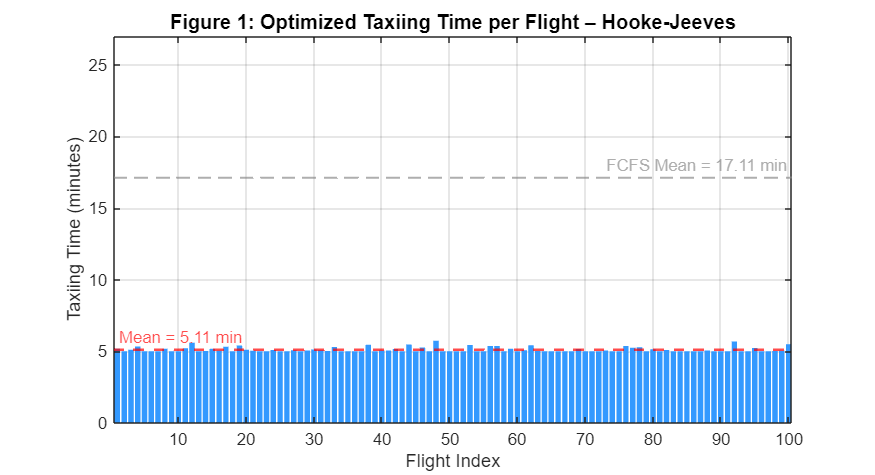


colors = struct( ...
    'fcfs', [0.55 0.55 0.55], ...
    'det',  [0.20 0.60 1.00], ...
    'ga',   [0.93 0.42 0.14], ...
    'pso',  [0.18 0.72 0.40]);

%% Figure 1 — Optimized Taxiing Time per Flight (Deterministic, last run)
figure('Name', 'Fig1: Taxiing Time', 'Color', 'w', 'Position', [50 500 700 380]);
bar(last_det_taxi, 'FaceColor', colors.det, 'EdgeColor', 'none');
hold on;
yline(mean(last_det_taxi), '--r', sprintf('Mean = %.2f min', mean(last_det_taxi)), ...
    'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', 10);
yline(FCFS.avg_taxi, '--', sprintf('FCFS Mean = %.2f min', FCFS.avg_taxi), ...
    'LineWidth', 1.2, 'Color', colors.fcfs, 'LabelHorizontalAlignment', 'right', 'FontSize', 10);
xlabel('Flight Index', 'FontSize', 11);
ylabel('Taxiing Time (minutes)', 'FontSize', 11);
title('Figure 1: Optimized Taxiing Time per Flight – Hooke-Jeeves', 'FontSize', 12, 'FontWeight', 'bold');
xlim([0.5 n+0.5]); ylim([0 TAXI_HI + 2]);
grid on; box on;

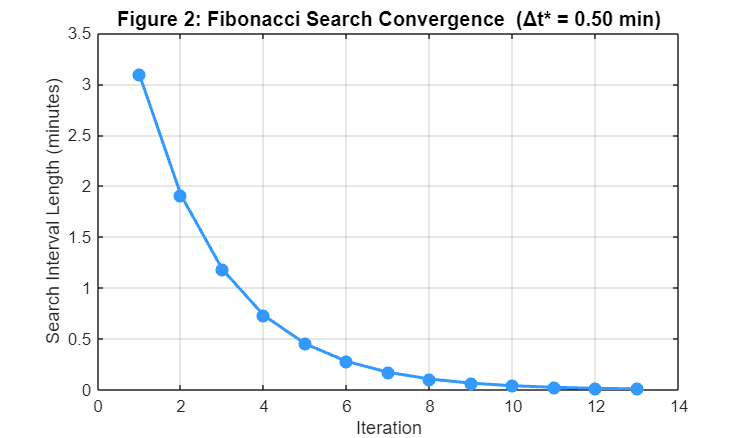


%% Figure 2 — Fibonacci Search Convergence
figure('Name', 'Fig2: Fibonacci Convergence', 'Color', 'w', 'Position', [50 80 600 350]);
plot(1:length(last_fib_intervals), last_fib_intervals, '-o', ...
    'Color', colors.det, 'LineWidth', 1.8, 'MarkerFaceColor', colors.det, 'MarkerSize', 6);
xlabel('Iteration', 'FontSize', 11);
ylabel('Search Interval Length (minutes)', 'FontSize', 11);
title(sprintf('Figure 2: Fibonacci Search Convergence  (Δt* = %.2f min)', last_det_offset), ...
    'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

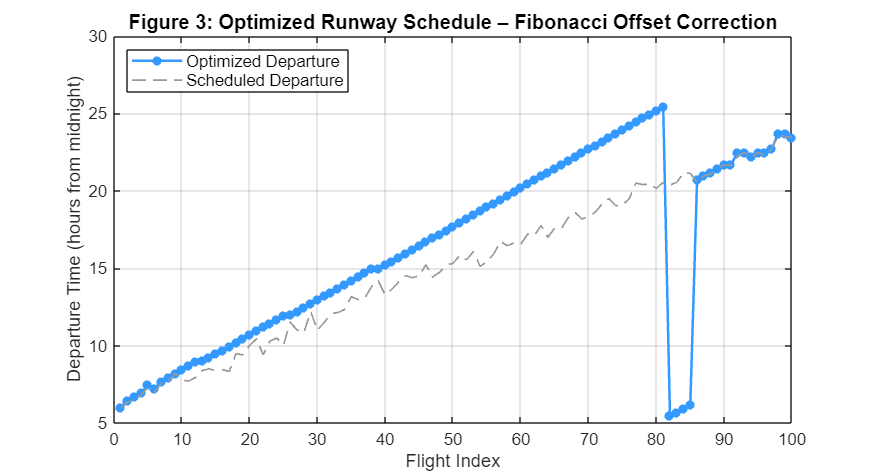


%% Figure 3 — Optimized Runway Schedule (Deterministic)
figure('Name', 'Fig3: Runway Schedule', 'Color', 'w', 'Position', [760 500 700 380]);
plot(1:n, last_det_adj_depart / 60, '-o', ...
    'Color', colors.det, 'LineWidth', 1.5, 'MarkerFaceColor', colors.det, 'MarkerSize', 4);
hold on;
plot(1:n, Depart_min / 60, '--', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.0);
legend({'Optimized Departure', 'Scheduled Departure'}, 'Location', 'northwest', 'FontSize', 10);
xlabel('Flight Index', 'FontSize', 11);
ylabel('Departure Time (hours from midnight)', 'FontSize', 11);
title('Figure 3: Optimized Runway Schedule – Fibonacci Offset Correction', ...
    'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

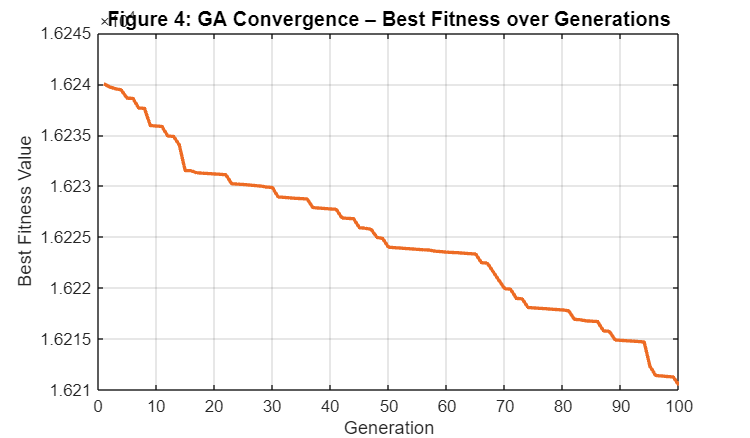


%% Figure 4 — GA Convergence Curve
figure('Name', 'Fig4: GA Convergence', 'Color', 'w', 'Position', [760 80 600 350]);
plot(1:GA_GENS, GA.conv_curve, '-', 'Color', colors.ga, 'LineWidth', 2);
xlabel('Generation', 'FontSize', 11);
ylabel('Best Fitness Value', 'FontSize', 11);
title('Figure 4: GA Convergence – Best Fitness over Generations', ...
    'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

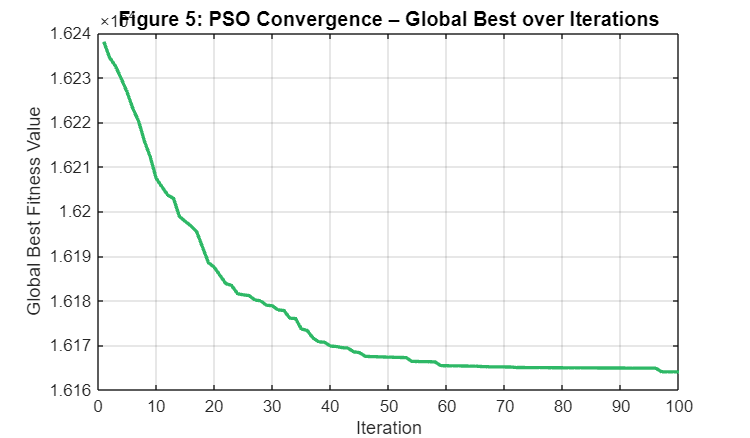


%% Figure 5 — PSO Convergence Curve
figure('Name', 'Fig5: PSO Convergence', 'Color', 'w', 'Position', [50 80 600 350]);
plot(1:PSO_ITERS, PSO.conv_curve, '-', 'Color', colors.pso, 'LineWidth', 2);
xlabel('Iteration', 'FontSize', 11);
ylabel('Global Best Fitness Value', 'FontSize', 11);
title('Figure 5: PSO Convergence – Global Best over Iterations', ...
    'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

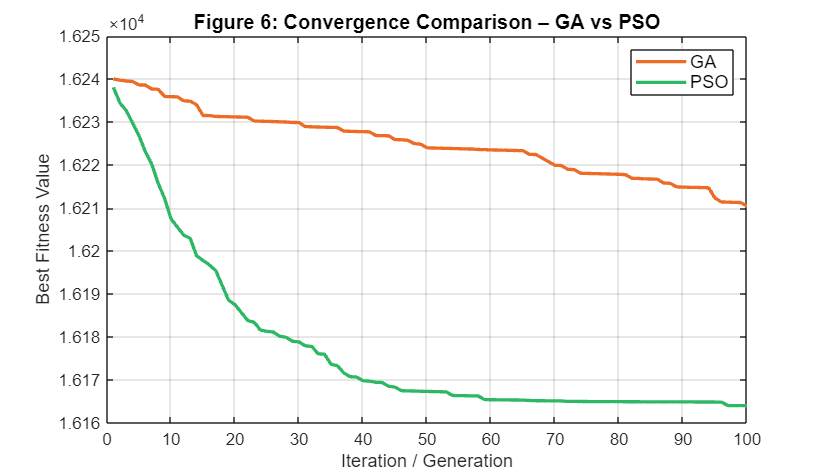


%% Figure 6 — GA vs PSO Convergence (overlaid)
figure('Name', 'Fig6: GA vs PSO Convergence', 'Color', 'w', 'Position', [760 80 660 380]);
iters_common = min(GA_GENS, PSO_ITERS);
plot(1:iters_common, GA.conv_curve(1:iters_common),  '-', 'Color', colors.ga,  'LineWidth', 2);
hold on;
plot(1:iters_common, PSO.conv_curve(1:iters_common), '-', 'Color', colors.pso, 'LineWidth', 2);
legend({'GA', 'PSO'}, 'Location', 'northeast', 'FontSize', 11);
xlabel('Iteration / Generation', 'FontSize', 11);
ylabel('Best Fitness Value', 'FontSize', 11);
title('Figure 6: Convergence Comparison – GA vs PSO', 'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

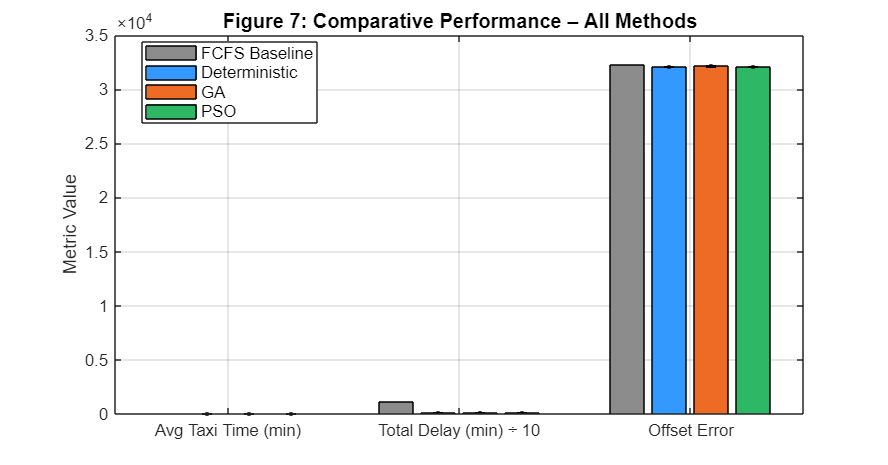


%% Figure 7 — Grouped Bar: All Methods vs All Metrics
figure('Name', 'Fig7: All Methods Comparison', 'Color', 'w', 'Position', [50 80 820 430]);
metric_labels = {'Avg Taxi Time (min)', 'Total Delay (min) ÷ 10', 'Offset Error'};
fcfs_vals = [FCFS.avg_taxi,    FCFS.total_delay/10,    FCFS.offset_err];
det_vals  = [DET.avg_taxi,     DET.total_delay/10,     DET.offset_err];
ga_vals   = [GA.avg_taxi,      GA.total_delay/10,      GA.offset_err];
pso_vals  = [PSO.avg_taxi,     PSO.total_delay/10,     PSO.offset_err];

det_err  = [DET.std_taxi,  DET.std_delay/10,  DET.std_offset];
ga_err   = [GA.std_taxi,   GA.std_delay/10,   GA.std_offset];
pso_err  = [PSO.std_taxi,  PSO.std_delay/10,  PSO.std_offset];

data_matrix = [fcfs_vals; det_vals; ga_vals; pso_vals];
b = bar(data_matrix', 'grouped');
b(1).FaceColor = colors.fcfs;
b(2).FaceColor = colors.det;
b(3).FaceColor = colors.ga;
b(4).FaceColor = colors.pso;

hold on;
ngroups = 3; nbars = 4;
groupwidth = min(0.8, nbars / (nbars + 1.5));
for i = 2:4
    x = (1:ngroups) - groupwidth/2 + (2*i-1)*groupwidth / (2*nbars);
    if i == 2, errs = det_err; elseif i == 3, errs = ga_err; else, errs = pso_err; end
    errorbar(x, data_matrix(i,:), errs, 'k.', 'LineWidth', 1.2);
end

set(gca, 'XTickLabel', metric_labels, 'FontSize', 10);
legend({'FCFS Baseline', 'Deterministic', 'GA', 'PSO'}, ...
    'Location', 'best', 'FontSize', 10);
ylabel('Metric Value', 'FontSize', 11);
title('Figure 7: Comparative Performance – All Methods', ...
    'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

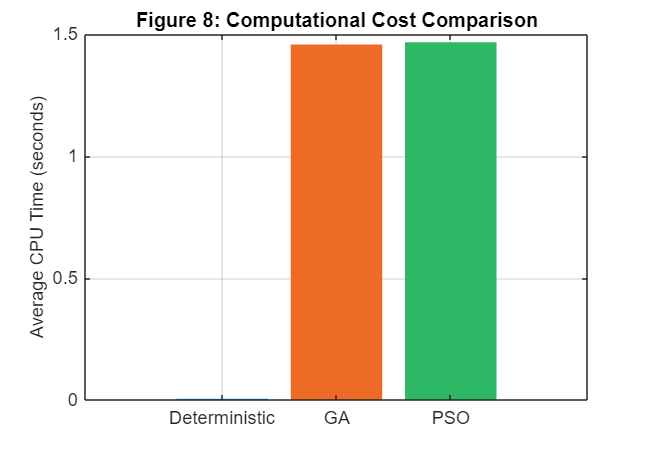


%% Figure 8 — CPU Time Comparison (bar)
figure('Name', 'Fig8: CPU Time', 'Color', 'w', 'Position', [760 80 520 360]);
cpu_vals = [DET.cpu, GA.cpu, PSO.cpu];
method_labels = {'Deterministic', 'GA', 'PSO'};
cpu_colors = [colors.det; colors.ga; colors.pso];
for i = 1:3
    bar(i, cpu_vals(i), 'FaceColor', cpu_colors(i,:), 'EdgeColor', 'none');
    hold on;
end
set(gca, 'XTick', 1:3, 'XTickLabel', method_labels, 'FontSize', 11);
ylabel('Average CPU Time (seconds)', 'FontSize', 11);
title('Figure 8: Computational Cost Comparison', 'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;

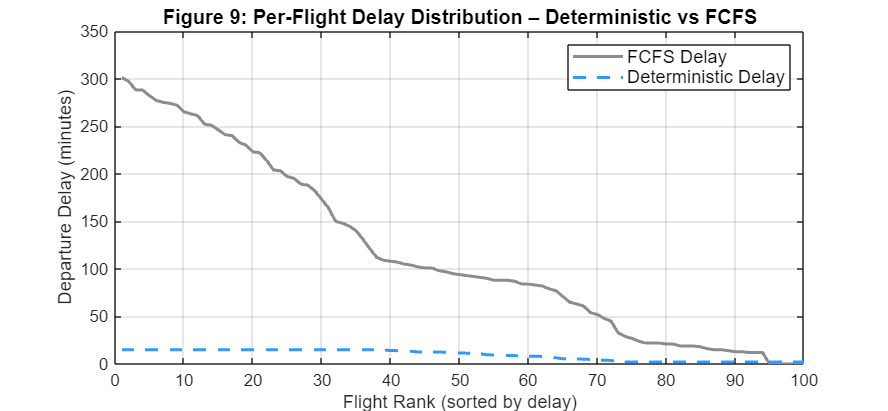


%% Figure 9 — Per-Flight Delay: Deterministic vs FCFS
figure('Name', 'Fig9: Per-Flight Delay', 'Color', 'w', 'Position', [50 80 820 380]);
plot(1:n, sort(fcfs_delay,     'descend'), '-',  'Color', colors.fcfs, 'LineWidth', 1.8);
hold on;
plot(1:n, sort(last_det_delay, 'descend'), '--', 'Color', colors.det,  'LineWidth', 1.8);
legend({'FCFS Delay', 'Deterministic Delay'}, 'Location', 'northeast', 'FontSize', 11);
xlabel('Flight Rank (sorted by delay)', 'FontSize', 11);
ylabel('Departure Delay (minutes)', 'FontSize', 11);
title('Figure 9: Per-Flight Delay Distribution – Deterministic vs FCFS', ...
    'FontSize', 12, 'FontWeight', 'bold');
grid on; box on;


fprintf('All figures generated successfully.\n');

All figures generated successfully.



function [avg_taxi, total_delay, offset_err] = evaluate_schedule( ...
    taxi_vec, Depart_min, Runway_slots, C_mean, ...
    DELAY_LO, DELAY_HI, OFFSET_LO, OFFSET_HI)

    n             = length(taxi_vec);
    slots_sorted  = sort(Runway_slots);
    assigned      = zeros(n, 1);
    delay         = zeros(n, 1);
    used          = false(length(slots_sorted), 1);
    alpha         = 0.02;
    grad_f        = @(d) 2 * d;

    earliest_ready = Depart_min + taxi_vec;

    for i = 1:n
        [~, idx] = min(abs(slots_sorted - earliest_ready(i)));
        cnt = 0;
        while used(idx) && cnt < length(slots_sorted)
            idx = mod(idx, length(slots_sorted)) + 1;
            cnt = cnt + 1;
        end
        assigned(i) = slots_sorted(idx);
        used(idx)   = true;

        d = assigned(i) - Depart_min(i);
        for iter = 1:15
            d_new = d - alpha * grad_f(d);
            if abs(alpha * grad_f(d)) < 1e-3, d = d_new; break; end
            d = d_new;
        end
        delay(i) = max(DELAY_LO, min(DELAY_HI, d));
    end

    avg_taxi    = mean(taxi_vec);
    total_delay = sum(delay);

    % Fibonacci Search for offset (fast, inline)
    f3 = @(x) sum(abs((assigned + x) - C_mean));
    a = 0; b = 5; fib = [1 1];
    while fib(end) <= (b-a)/1e-3, fib = [fib, fib(end-1)+fib(end)]; end
    for k = length(fib):-1:3
        x1 = a + fib(k-2)/fib(k)*(b-a);
        x2 = a + fib(k-1)/fib(k)*(b-a);
        if f3(x1) > f3(x2), a = x1; else, b = x2; end
        if (b-a) < 1e-2, break; end
    end
    opt_off    = max(OFFSET_LO, min(OFFSET_HI, (a+b)/2));
    offset_err = sum(abs((assigned + opt_off) - C_mean));
end

% MATLAB Script: save_figures.m
% Use this script to export all currently open figure windows as 
% separate, high-resolution, cropped PNG files for your journal submission.

% 1. Get all currently open figure handles
figs = findobj('Type', 'figure');

if isempty(figs)
    fprintf('No active figure windows found.\n');
    fprintf('Please run your main optimization script first to display the figures,\n');
    fprintf('then run this save_figures.m script again.\n');
    return;
end

% 2. Sort the figures by their figure number (Figure 1, Figure 2, etc.)
figNumbers = [figs.Number];
[~, sortIdx] = sort(figNumbers);
figs = figs(sortIdx);

fprintf('Found %d open figures. Exporting to high-resolution PNGs...\n', length(figs));

Found 9 open figures. Exporting to high-resolution PNGs...


  [Success] Saved Figure 1 as "Figure1.png"


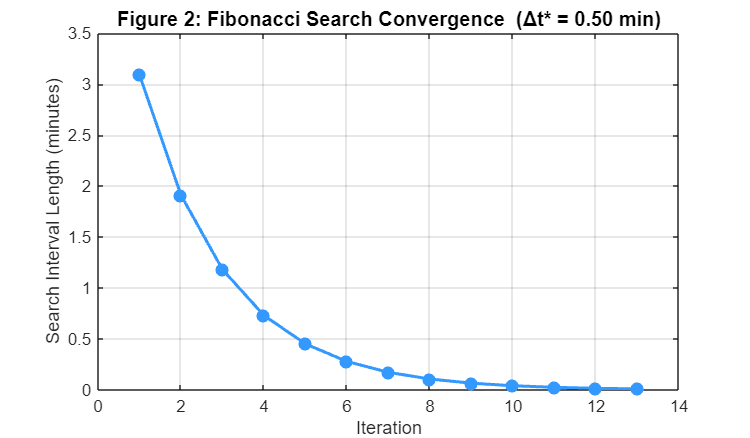

  [Success] Saved Figure 2 as "Figure2.png"


  [Success] Saved Figure 3 as "Figure3.png"


  [Success] Saved Figure 4 as "Figure4.png"


  [Success] Saved Figure 5 as "Figure5.png"


  [Success] Saved Figure 6 as "Figure6.png"


  [Success] Saved Figure 7 as "Figure7.png"


  [Success] Saved Figure 8 as "Figure8.png"


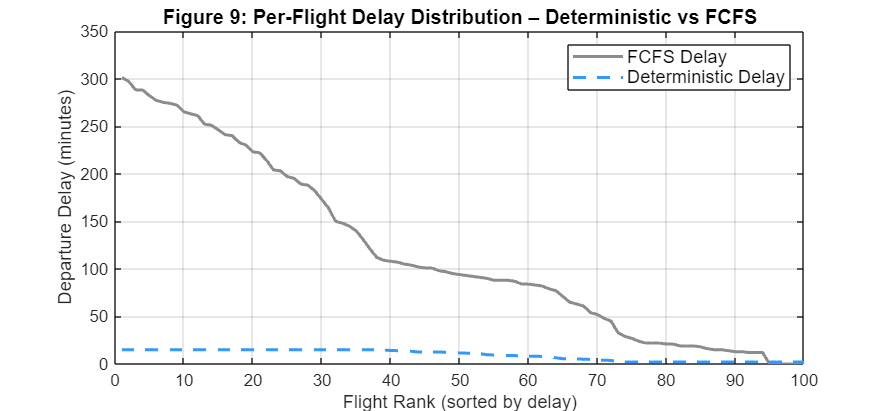

  [Success] Saved Figure 9 as "Figure9.png"



% 3. Export each figure
for i = 1:length(figs)
    current_fig = figs(i);
    fig_num = current_fig.Number;
    output_filename = sprintf('Figure%d.png', fig_num);
    
    try
        % exportgraphics automatically crops excess whitespace and exports at 220 DPI
        exportgraphics(current_fig, output_filename, 'Resolution', 220);
        fprintf('  [Success] Saved Figure %d as "%s"\n', fig_num, output_filename);
    catch ME
        % Fallback for older MATLAB versions (prior to R2020a)
        fprintf('  exportgraphics failed for Figure %d. Trying print fallback...\n', fig_num);
        try
            % Crop margins using tight print options
            set(current_fig, 'PaperPositionMode', 'auto');
            print(current_fig, output_filename, '-dpng', '-r220');
            fprintf('  [Success] Saved Figure %d as "%s" (via print)\n', fig_num, output_filename);
        catch ME_inner
            fprintf('  [Error] Could not save Figure %d. Message: %s\n', fig_num, ME_inner.message);
        end
    end
end


fprintf('All open figures processed.\n');

All open figures processed.
